# **MAE315 Lab 1 - Prosethic Material**

## Contents

- **Project Description**

- **Procedure**

- **Data **

- **Equations**

- **Code**

- **Outcome**

## **[1.] Project Description **

Through use of MTS machine and Extensometer determine the best material out of Steel, Aluminum, Carbon FIber 45, Carbon FIber 90, PLA to be used in a prosthetic.

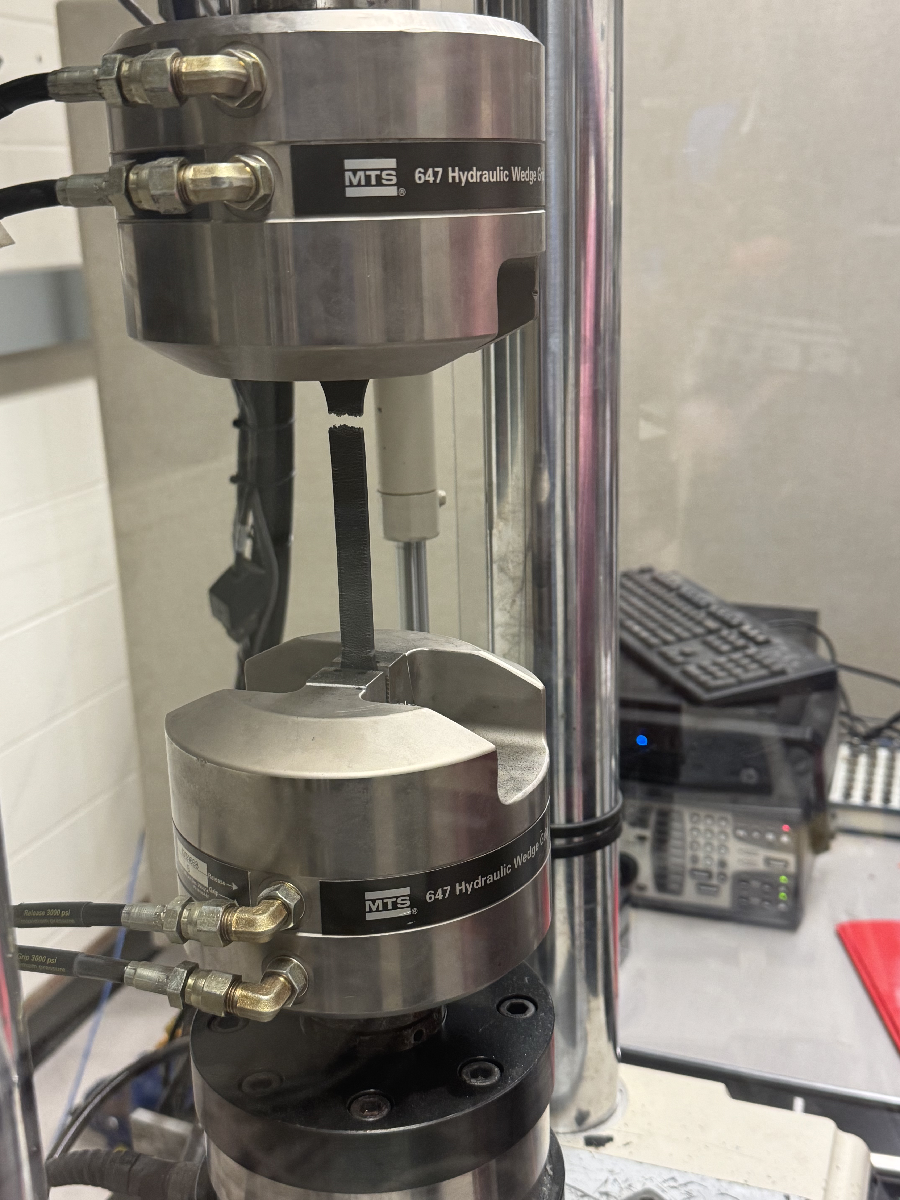

*fig. 1 PLA fracture in MTS*

## **[2.] Procedure**

MTS and Extensometer experiment on several materials, Steel, Aluminum, Carbon FIber 45, Carbon FIber 90, PLA plastic. Stress Strain curves of each material, where the key points of each material are found though use of matlab code and math, 0.02% offset method. Error pick the best material for a prostheic matrix decision like in materials class. Do everything in the most efficient manner        

## [3.] Data

The experiment generates a text file with three columns. The first and second columns given by the MTS are force and dispalcement, respectivley. The third column given by the extensometer is strain. The strain data was supplied for each material but only used for steel, the data of which is given below. 

filename = '/Users/darrenprashad/Documents/MATLAB/MAE315/datasets/M003/Steel.dat';
DATA = readmatrix(filename)                       

DATA = 1.0e+03 *

    0.0380    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0702    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0865    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.0971    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1225    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1562    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1932    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2263    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.2659    0.0000    0.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.3203    0.0000    0.0000       NaN       NaN       NaN       NaN   

## [4.] Equations

Below are the list of equations used to find key values of each material, which were then used to find the most optimate material

- 
$$\sigma =\frac{F}{W_0 t_0 }$$


- 
$$\epsilon =\frac{L}{L_0 }$$


- 
$$\sigma_{\mathrm{TR}} =\sigma \left(1+\epsilon \right)\;$$


- 
$$\epsilon_{\mathrm{TR}} =\ln \left(1+\epsilon \right)$$


- 
$$U_{\sigma } =\sqrt{{\left(\frac{\partial \sigma }{\partial F}U_F \right)}^2 +{\left(\frac{\partial \sigma }{\partial W_0 }U_{W_0 } \right)}^2 +{\left(\frac{\partial \sigma }{\partial t_0 }U_{t_0 } \right)}^2 }$$


- 
$$U_{\varepsilon } =\sqrt{{\left(\frac{\partial \varepsilon }{\partial D}U_D \right)}^2 +{\left(\frac{\partial \epsilon }{\partial L_0 }U_{l_0 } \right)}^2 }$$


- 
$$E=\frac{1}{n}\sum_{n=1}^N \frac{\sigma }{\epsilon }$$


- 
$${\mathrm{Mod}}_R =\int_0^{\epsilon_{\mathrm{Yeild}} } \sigma \;d\epsilon$$


- 
$${\mathrm{Mod}}_T =\int_0^{\epsilon_{\mathrm{Fracture}} } \sigma \;d\epsilon$$


## [5.] Code

*the following example is given for steel, following up on the previous example of file import*

#### Symbolics

Use of symbolics to maximize efficiency and abstraction

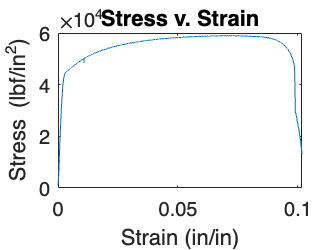

syms stress strain D F L0 T0 W0 

stress = F/(W0*T0);
strain = D/L0;
stress_t = (F/(W0*T0).*(1+D/L0));
strain_t = log(1 + D/L0);
youngsmodulus = (F*L0)/(W0*T0*D);

W0 = 0.511;
T0 = 0.0585;
L0 = 6.48;
F = DATA(:,1); 
D = DATA(:,2);
STRESS = eval(stress);
STRAIN = eval(strain);
plot(STRAIN,STRESS)
xlabel('Strain (in/in)')
ylabel('Stress (lbf/in^2)')
title('Stress v. Strain')

#### Yeild Point, Ultimate Point, Rupture Points

INDEX = 100;
% finds ULTIMATE POINT
ultimatePOINTY = max(STRESS);
ULT_I = find(abs(STRESS-ultimatePOINTY) < 0.001);
ultimatePOINTX = STRAIN(ULT_I, 1);
ULTIMATE_POINTS = [ultimatePOINTX ultimatePOINTY]

ULTIMATE_POINTS = 1.0e+04 *

    0.0000    5.8973



% finds FRACTURE POINT
sz = size(STRESS);
length = sz(1,1);
fractureX = STRAIN(length);
fractureY = STRESS(length);
RUPTURE_POINTS = [fractureX fractureY]

RUPTURE_POINTS = 1.0e+04 *

    0.0000    1.2935



% finding yeild point / finding young modules / 0.2% offset
p = polyfit(STRAIN(1:INDEX,1),STRESS(1:INDEX,1), 1);
youngsMODULUS = p(1,1);
YOUNGS = youngsMODULUS

YOUNGS = 7.9422e+06


OFFSETx = STRAIN(1:length,1);
OFFSETy = YOUNGS*(OFFSETx-0.002);

YEILD_I = find(OFFSETy >= STRESS, 1); % i represents index of yeild point

OFFSETx = OFFSETx(1:YEILD_I,1);
OFFSETy = OFFSETy(1:YEILD_I,1);
OFFSET = [OFFSETx, OFFSETy];

YEILDx = OFFSETx(YEILD_I,1);
YEILDy = OFFSETy(YEILD_I,1);
YEILD_POINTS = [YEILDx YEILDy]

YEILD_POINTS = 1.0e+04 *

    0.0000    4.8627


## [6.] Outcome